# EXP.7. State Estimation of the Coupled Tanks System

h1 = 0 % cm

h1 = 0

h2 = 0 % cm

h2 = 0

g = 981 % cm/s^2

g = 981

d = 4.45 % cm

d = 4.4500

A_1 = (pi*d^2)/4 % cm^2

A_1 = 15.5528

A_2 = A_1 % cm^2

A_2 = 15.5528

d_or = 0.48 % cm

d_or = 0.4800

A_b = (pi*d_or^2)/4 % cm^2

A_b = 0.1810

A_e = A_b % cm^2

A_e = 0.1810

c_1 = A_b*sqrt(2*g)

c_1 = 8.0153

c_2 = A_e*sqrt(2*g)

c_2 = 8.0153

h_10 = 14.5  % cm

h_10 = 14.5000

h_20 = 14.5  % cm

h_20 = 14.5000

q_i0 = 20  % cm^3/s

q_i0 = 20

A = [-c_1/(2*A_1*sqrt(h_10)) 0; c_1/(2*A_2*sqrt(h_10)) -c_2/(2*A_2*sqrt(h_20))]

A =    -0.0677         0
    0.0677   -0.0677


B = [1/A_1; 0]

B =     0.0643
         0


C = [0 1];

w_n = 0.2 % rad/s

w_n = 0.2000

DesPoles = roots([1 1.4*w_n w_n^2])

DesPoles =   -0.1400 + 0.1428i
  -0.1400 - 0.1428i


G = acker(A',C',DesPoles)'

G =     0.3788
    0.1447


T = 1;  % s

T = 1

phi_obs = eye(2) + (A-G*C)*T

phi_obs =     0.9323   -0.3788
    0.0677    0.7877


gamma_u = B*T

gamma_u =     0.0643
         0


gamma_y = G*T

gamma_y =     0.3788
    0.1447


data = [1.002,8.853712,3.720259,14.0235,3.850686,0.74
2.007,5.68037,3.766292,11.98732,3.850686,0.74
3.012,3.562759,4.55652,10.26682,4.034816,0.74
4.017,2.318584,5.438814,8.857404,4.241963,0.74
5.022,1.759287,6.313436,7.734928,4.418422,0.74
6.027,1.770521,7.188057,6.892612,4.702291,0.74
7.032001,2.169785,7.786482,6.282799,4.886421,0.74
8.037001,2.871813,8.523006,5.887709,5.147274,0.74
9.042001,3.768975,9.159792,5.672733,5.392781,0.74
10.047,4.808905,9.850283,5.62039,5.715011,0.74
11.052,5.902905,10.18018,5.693146,5.991207,0.74
12.057,7.014461,10.84766,5.871176,6.305764,0.74
13.062,8.137382,11.24661,6.146215,6.712386,0.74
14.067,9.190564,11.68392,6.476299,7.003926,0.74
15.072,10.16369,12.14425,6.846542,7.310811,0.74
16.077,11.04406,12.50484,7.241031,7.610024,0.74
17.082,11.87236,12.85008,7.66774,8.024319,0.74
18.087,12.60213,13.14929,8.098733,8.338875,0.74
19.092,13.20063,13.55592,8.509789,8.553694,0.74
20.097,13.71627,13.78608,8.911745,8.852907,0.74
21.102,14.14938,14.12365,9.297617,9.129103,0.74
22.107,14.50002,14.25408,9.660799,9.374611,0.74
23.112,14.82885,14.49959,10.02239,9.742872,0.74
24.117,15.09146,14.81414,10.36049,9.98838,0.74
25.122,15.30995,15.01362,10.68044,10.2569,0.74
26.127,15.49708,15.15172,10.98507,10.5331,0.74
27.132,15.66369,15.43559,11.27735,10.81697,0.74
28.136,15.79258,15.51231,11.54848,11.03946,0.74
29.141,15.92339,15.62739,11.81418,11.33867,0.74
30.146,16.0377,15.79618,12.06671,11.58418,0.74
31.151,16.10384,16.16444,12.29119,11.72995,0.74
32.156,16.1415,16.21047,12.49386,11.89107,0.74
33.161,16.22481,16.3946,12.70685,12.22097,0.74
34.166,16.27991,16.46365,12.90055,12.37441,0.74
35.171,16.3422,16.7245,13.08952,12.5969,0.74
36.176,16.41879,16.64011,13.27795,12.83474,0.74
37.181,16.46821,16.8626,13.44859,12.96516,0.74
38.186,16.54847,17.1388,13.62616,13.22602,0.74
39.191,16.61415,17.11578,13.79267,13.37946,0.74
40.196,16.6501,17.1388,13.94068,13.47919,0.74
41.201,16.72345,17.1925,14.09886,13.73237,0.74
42.206,16.82782,17.57611,14.26714,13.98555,0.74
43.211,16.86429,17.46103,14.40326,13.99323,0.74
44.216,16.95136,17.5224,14.55633,14.26942,0.74
45.221,17.01523,17.69119,14.69676,14.37683,0.74
46.226,17.03903,17.70653,14.81564,14.42286,0.74
47.231,17.16149,17.94437,14.97305,14.80647,0.74
48.236,17.23929,17.81394,15.11119,14.86785,0.74
49.241,17.33215,17.92135,15.25403,15.05965,0.74
50.246,17.37043,18.08247,15.37134,15.075,0.74
51.251,17.41109,17.99807,15.48537,15.20542,0.74
52.256,17.42906,18.05945,15.58528,15.2668,0.74
53.261,17.48933,18.15919,15.69913,15.48162,0.74
54.266,17.59539,18.2666,15.8315,15.72713,0.74
55.271,17.60636,18.31263,15.92208,15.62739,0.74
56.276,17.66656,18.36633,16.02968,15.84988,0.74
57.281,17.7197,18.31263,16.13246,15.94962,0.74
58.286,17.74484,18.41237,16.22067,15.98798,0.74
59.291,17.7494,18.4047,16.29601,16.02634,0.74
60.297,17.79196,18.50443,16.38375,16.2028,0.74
61.302,17.85942,18.54279,16.48074,16.36391,0.74
62.307,15.15978,18.50443,15.33342,9.167463,0.74
63.312,15.84388,18.52745,15.53257,16.47132,0.74
64.317,16.48763,18.71158,15.76407,16.68614,0.74
65.32201,16.99722,18.68089,15.97979,16.67847,0.74
66.327,17.43131,18.56581,16.19463,16.78588,0.74
67.332,17.75464,18.68856,16.38572,16.78588,0.74
68.33701,17.99244,18.66555,16.55566,16.8089,0.74
69.342,18.21079,18.78063,16.7276,16.97001,0.74
70.347,18.326,18.81899,16.86196,16.90863,0.74
71.35201,18.48133,18.71925,17.01603,17.16948,0.74
72.357,18.57069,18.86502,17.14454,17.17716,0.74
73.36201,18.61695,18.82666,17.25333,17.20784,0.74
74.367,18.64503,18.77296,17.35092,17.27689,0.74
75.372,18.68655,18.86502,17.45057,17.41499,0.74
76.37701,18.69914,18.95709,17.53435,17.44568,0.74
77.382,18.67334,18.94174,17.59638,17.43034,0.74
78.387,18.65484,18.91873,17.65508,17.50706,0.74
79.39201,18.64442,18.89571,17.71172,17.58378,0.74
80.397,18.63069,18.94942,17.76206,17.62981,0.74
81.402,18.64242,19.03381,17.81915,17.74489,0.74
82.40701,18.61138,18.98778,17.85425,17.69119,0.74
83.412,18.58368,18.94174,17.88557,17.72955,0.74
84.41701,18.59248,19.1182,17.92859,17.8523,0.74
85.422,18.60765,18.99545,17.97239,17.91368,0.74
86.427,18.58194,19.05683,17.99626,17.8523,0.74
87.43201,18.56928,19.1182,18.02198,17.90601,0.74
88.437,18.5797,19.05683,18.05515,17.9904,0.74
89.442,18.5565,19.07217,18.07195,17.9367,0.74
90.44701,18.58664,19.17958,18.10941,18.09014,0.74
91.452,18.60926,19.13355,18.14377,18.11316,0.74
92.457,18.62606,19.10286,18.17531,18.13617,0.74
93.46201,18.66755,19.05683,18.21739,18.23591,0.74
94.467,18.69611,19.15656,18.25468,18.25125,0.74
95.47201,18.69698,19.21794,18.27967,18.22056,0.74
96.47701,18.71158,19.1182,18.30923,18.28194,0.74
97.483,18.73724,19.18725,18.34312,18.34332,0.74
98.48701,18.75705,19.10286,18.37449,18.36633,0.74
99.493,18.7491,19.23328,18.39311,18.32797,0.74
100.498,18.7637,19.23328,18.41986,18.4047,0.74
101.503,18.77589,19.21027,18.44509,18.42771,0.74
102.508,12.80591,18.69624,15.78024,2.661507,0.74
103.513,14.21528,17.56076,16.0551,18.41237,0.74
104.518,15.35832,16.55571,16.32342,18.23591,0.74
105.523,16.25554,15.71945,16.56996,18.05945,0.74
106.528,16.9638,14.76044,16.79876,17.96738,0.74
107.533,14.45421,13.8091,15.63161,9.827267,0.74
108.538,15.45671,13.01887,15.88775,17.48404,0.74
109.543,16.19554,12.4051,16.10176,17.22319,0.74
110.548,16.66674,12.3207,16.25005,16.8626,0.74
111.553,16.9656,12.50484,16.3549,16.64011,0.74
112.558,17.1377,12.84241,16.4236,16.46365,0.74
113.563,17.19947,13.31041,16.45415,16.27185,0.74
114.568,17.199,13.47152,16.46042,16.14909,0.74
115.573,17.16422,13.97788,16.4508,16.0647,0.74
116.578,17.10346,14.20037,16.42691,15.98031,0.74
117.583,17.00357,14.34614,16.38135,15.84221,0.74
118.588,16.86666,14.70673,16.31289,15.68109,0.74
119.593,16.77658,14.83716,16.25731,15.71178,0.74
120.598,16.72526,15.02129,16.2145,15.74247,0.74
121.603,16.62099,15.15939,16.14598,15.55067,0.74
122.608,16.55553,15.44326,16.08979,15.56601,0.74
123.613,16.49835,15.66575,16.03501,15.51998,0.74
124.618,16.4716,15.81919,15.99227,15.53532,0.74
125.623,16.44542,16.03401,15.95017,15.48929,0.74
126.636,16.45439,16.28719,15.92428,15.53532,0.74
127.641,16.51615,16.40227,15.92471,15.6504,0.74
128.646,16.54741,16.3946,15.91718,15.58136,0.74
129.651,16.6259,16.61709,15.93431,15.70411,0.74
130.656,16.68969,16.66312,15.95102,15.69644,0.74
131.661,16.73702,16.97001,15.96516,15.68109,0.74
132.666,16.83682,16.93932,16.00636,15.84221,0.74
133.671,16.91426,17.0544,16.04405,15.84221,0.74
134.676,16.98962,17.10044,16.08549,15.88824,0.74
135.681,17.06743,17.25388,16.13229,15.94962,0.74
136.686,17.13387,17.25388,16.17808,15.98031,0.74
137.691,17.21335,17.43801,16.23284,16.07237,0.74
138.696,17.27542,17.54542,16.28351,16.09539,0.74
139.701,17.38094,17.76791,16.35608,16.27185,0.74
140.706,17.43439,17.75257,16.41021,16.22581,0.74
141.711,17.49859,17.89066,16.4705,16.31788,0.74
142.716,17.56758,17.83696,16.53487,16.40227,0.74
143.721,17.62206,17.90601,16.59481,16.44063,0.74
144.726,17.65014,17.97506,16.64392,16.44063,0.74
145.731,17.68968,18.05178,16.69748,16.52503,0.74
146.736,17.73241,18.03643,16.75256,16.59407,0.74
147.742,17.76592,18.14384,16.80376,16.63243,0.74
148.746,17.82137,18.1285,16.86448,16.74752,0.74
149.751,17.83552,18.15152,16.90772,16.70916,0.74
150.757,17.87303,18.27427,16.95986,16.81657,0.74
151.762,17.94346,18.29729,17.02678,16.96234,0.74
152.767,17.96635,18.32797,17.07438,16.9163,0.74
153.772,18.00453,18.38168,17.12777,17.00837,0.74
154.777,18.0693,18.48909,17.19308,17.1388,0.74
155.782,18.10495,18.49676,17.24693,17.1388,0.74
156.787,18.14104,18.49676,17.30067,17.20017,0.74
157.792,18.1369,18.63486,17.33606,17.15414,0.74
158.797,18.18937,18.58115,17.39412,17.33827,0.74
159.802,18.20468,18.55814,17.43646,17.30758,0.74
160.807,18.2407,18.61951,17.48666,17.40732,0.74
161.812,18.29013,18.5965,17.54288,17.49939,0.74
162.817,18.32365,18.6502,17.59275,17.5224,0.74
163.822,18.34472,18.71925,17.63679,17.54542,0.74
164.827,18.38256,18.7883,17.68736,17.63748,0.74
165.832,18.39578,18.74227,17.72697,17.62981,0.74
166.837,18.40472,18.84201,17.76322,17.6605,0.74
167.842,18.39352,18.74994,17.78879,17.64515,0.74
168.847,18.38792,18.85735,17.8141,17.68352,0.74
169.852,18.42832,18.81899,17.85786,17.82929,0.74
170.857,18.45523,18.83433,17.89637,17.84463,0.74
171.862,18.47445,18.79597,17.93134,17.86765,0.74
172.867,18.50237,18.81899,17.96964,17.92902,0.74
173.872,18.49936,18.96476,17.99406,17.89066,0.74
174.877,18.51637,18.94942,18.02555,17.96738,0.74
175.882,18.51158,18.88804,18.04669,17.94437,0.74
176.888,18.51945,18.93407,18.07165,17.99807,0.74
177.893,18.54929,18.88804,18.10554,18.08247,0.74
178.898,18.55557,18.89571,18.12932,18.05945,0.74
179.903,18.596,18.99545,18.16744,18.17453,0.74
180.908,18.61054,18.94942,18.19512,18.15152,0.74
181.913,18.63686,18.9264,18.22759,18.21289,0.74
182.918,18.66653,19.04148,18.26182,18.25892,0.74
183.923,18.67542,19.01079,18.28717,18.24358,0.74
184.928,18.69736,19.01847,18.3175,18.30496,0.74
185.933,18.68016,19.19492,18.33024,18.23591,0.74
186.938,18.71162,19.01079,18.36238,18.37401,0.74
187.943,18.73458,19.17958,18.39147,18.38935,0.74
188.948,18.75079,19.04148,18.4177,18.4047,0.74
189.953,12.76673,18.95709,15.74602,2.592458,0.74
190.958,14.1888,19.13355,16.02525,18.4047,0.74
191.963,15.42922,19.14122,16.33689,18.4584,0.74
192.968,16.42697,19.12587,16.63434,18.35099,0.74
193.973,17.27359,19.30233,16.93703,18.42771,0.74
194.978,17.96572,19.20259,17.22894,18.47374,0.74
195.983,18.50625,19.10286,17.49767,18.48909,0.74
196.988,12.99474,19.11053,15.07784,2.876326,0.74
197.993,14.71259,19.21027,15.55658,18.55814,0.74
198.998,16.13286,19.23328,16.02978,18.55814,0.74
200.003,11.34377,19.15656,13.81212,2.891671,0.74];

t = data(:, 1);
h1_hat = data(:, 2);
h1 = data(:, 3);
h2_hat = data(:, 4);
h2 = data(:, 5);
dc = data(:, 6);

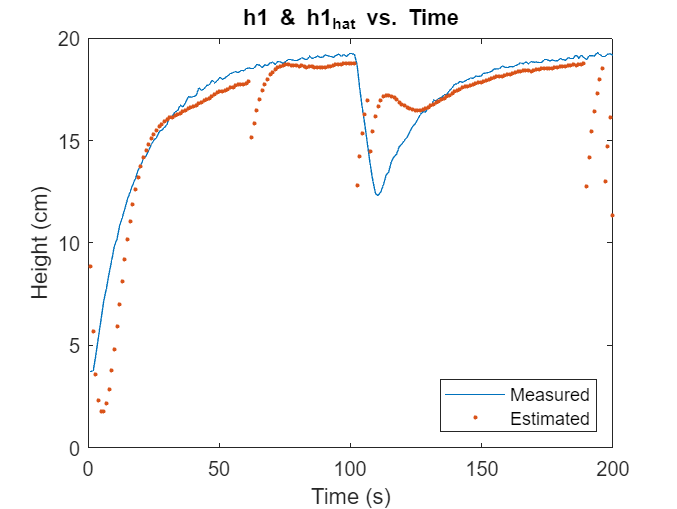

% h1 plot
plot(t, h1)
hold on 
plot(t, h1_hat, '.')
hold off
title("h1 & h1_{hat} vs. Time")
xlabel("Time (s)")
ylabel("Height (cm)")
legend('Measured', 'Estimated', 'Location', 'southeast')

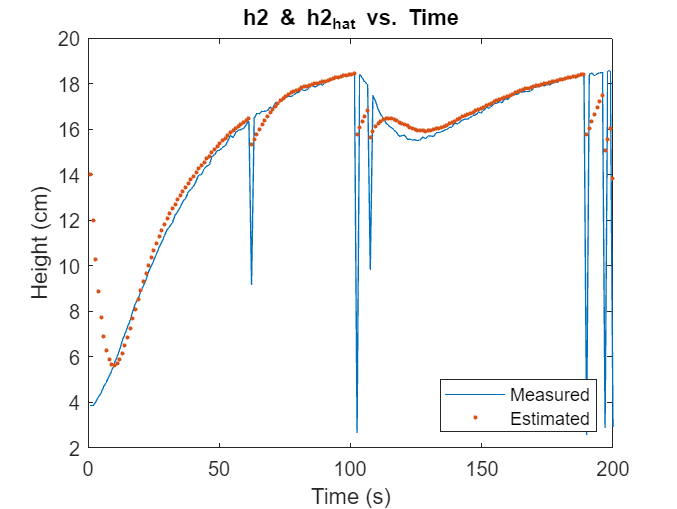


% h2 plot
plot(t, h2)
hold on 
plot(t, h2_hat, '.')
hold off
title("h2 & h2_{hat} vs. Time")
xlabel("Time (s)")
ylabel("Height (cm)")
legend('Measured', 'Estimated', 'Location', 'southeast')

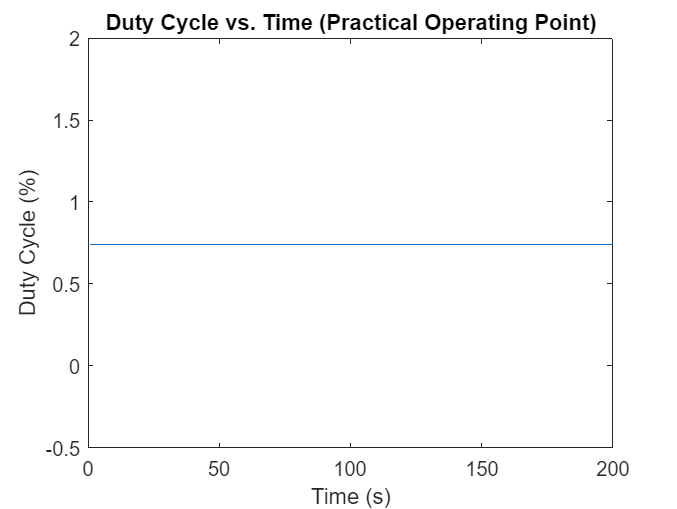


% duty cycle plot
plot(t, dc)
title("Duty Cycle vs. Time (Practical Operating Point)")
xlabel("Time (s)")
ylabel("Duty Cycle (%)")